# Pozrikidis Channel Stokeslets Only

## Boundary Velocity

The velocity at the top and bottom boundary are given by:


$$v(x,\pm H) = \left\{ \begin{array}{lr} 0, & x\in[-L-c,-L]\cup [L,L+c]\\ \pm {\rm Da}\, p_T(x) & x\in(-L,L) \end{array} \right.$$


We have two options for computing the velocity boundary conditions using $p_T(x)$ in the permeable region:

1. Following Pozrikidis: 


$$p_T(x,\pm H) = \left\{ \begin{array}{lr} \gamma\sinh(\alpha(-L))-G(x+L), & x\in[-L-c,-L]\\ \gamma\sinh(\alpha x) & x\in(-L,L) \\ \gamma\sinh(\alpha L)-G(x-L), & x\in[L,L+c] \end{array} \right.$$


2. Following Bernardi: 


$$p_T(x,\pm H) = \left\{ \begin{array}{lr} -Gx - GL +  \frac{G}{\lambda}\tanh(\lambda L), & x\in (-L-c,-L)\\ -\frac{G}{\lambda\cosh(\lambda L)}\sinh(\lambda x) & x\in(-L,L) \\ -Gx+ GL- \frac{G}{\lambda}\tanh(\lambda L), & x\in (L,L+c)\end{array} \right.$$


where $\alpha$, $\gamma$, and $x_m$ are defined above and $\lambda$ satisfies $0=({\rm Da}-H/2)\lambda\cot(\lambda H)\cos(\lambda H) + \frac12\cos(\lambda H)-\frac{\lambda H}{2}\sin(\lambda H)$.

For ${\rm Da}=0.3, H=1$, we have $\lambda\approx 0.74$.

In the non-permeable region, we have $v=0$ and $u=0$. At the inlet, we have fully developed Poiseuille flow ($u=u_{pois}$, $v=0$). At the outlet, the Poiseuille flow is scaled by a factor $\chi$ to give $u=\chi u_{pois}$ and $v=0$.

## Pozrikidis

The velocity boundary conditions in this instance are


$$v(x,\pm H) = \left\{ \begin{array}{lr} 0, & x\in[-L-c,-L]\cup [L,L+c]\\ \pm{\rm Da}\,\gamma\sinh(\alpha x) & x\in(-L,L) \end{array} \right.$$



$$u(x,\pm H) = 0\quad\text{for}\quad x\in[-L-c,L+c].$$


## Bernardi

The velocity boundary conditions in this instance are


$$v(x,\pm H) = \left\{ \begin{array}{lr} 0, & x\in[-L-c,-L]\cup [L,L+c]\\ \mp\frac{{\rm Da} \, G}{\lambda\cosh(\lambda L)}\sinh(\lambda x) & x\in(-L,L) \end{array} \right.$$



$$u(x,\pm H) = 0\quad\text{for}\quad x\in[-L-c,L+c]$$


clear
close all 

addpath('./stokeslets_codes'); 

method_for_plots = 'Stokeslets Only (channel with permeable section)';

#### **Set parameters**

- Blob choice 2 uses $\psi$ from 2021 paper

- Blob choice 1 uses $\phi$ from 2021 paper

%set Darcy number
Da = 0.3;
%viscosity
mu = 1; 
%choose blob
blob_num = 2;
% scale factor for epsilon*ds_y
ep_factor = 1;
C = 0.39; %constant for beta_value when V = 0 (velocity for Step 1 permeable) 

% Poiseuille flow strength
G = 1;
% chi in PC paper: "dimensionless coeff. determining exit flow rate"
chi = 1;

% Number of source and target points
N = 160; % Number of source points (along top  and bottom boundaries)
Nx2 = 40; % Number of target points in y direction for full channel calc
Nx1 = floor(pi*Nx2); % Number of target points in x direction for full channel calc

#### **Define geometry and regularization**

% Setting forces and computing velocity 
% Channel geometry

L = 2; % length of permeable portion of the channel
H = 1; % radius of the channel
c = 2*H; % extension length of the channel
alpha = sqrt(3*mu*Da/(H^3)); % needed for CP solution
gamma = -chi/(alpha*cosh(alpha*L/2)); % needed for CP solution
lambda = 0.74; % needed for FB solution

xmin = -L - c;
xmax = L + c;
ymin = -H;
ymax = H;

% Discretization step
ds_x = (xmax - xmin)/N;
ds_y = (ymax - ymin)/( ceil((ymax - ymin)/ds_x));

% Define blob size based on wall discretization 
ep = ds_y*ep_factor;

% beta value based on Da, epsilon, and C
beta_value = Da*ep*C;

#### **Discretization**

tb = top/bottom

lr = left/right

source point coordinates organized stacked:

    [top; bottom; left; right]

%discretization step of top/bottom walls
stb = xmin+ds_x/2:ds_x:xmax-ds_x/2;
stb = stb';
%discretization step of left/right wall (inlet/outlet)
slr = ymin+ds_y/2:ds_y:ymax-ds_y/2;
slr = slr';

% Define coordinates on each wall (x-coord,y-coord) (source points)
y1_top = stb;   y2_top = ymax*ones(size(stb)); % top wall coordinates (y1_top,y2_top)
y1_bot = stb;   y2_bot = ymin*ones(size(stb)); % bottom wall coordinates (y1_bot,y2_bot)
y1_left = xmin*ones(size(slr));   y2_left = slr; % left wall coordinates (y1_left,y2_left)
y1_right = xmax*ones(size(slr));   y2_right = slr; % right wall coordinates (y1_right,y2_right)
y1 = [y1_top; y1_bot; y1_left; y1_right]; %x-coordinates of all boundary points
y2 = [y2_top; y2_bot; y2_left; y2_right]; %y-coordinates of all boundary points

% Define normal vectors
normals_top = zeros(length(stb),2); % unit normals for top:
normals_top(:,2) = 1;
normals_bot = zeros(length(stb),2); % unit normals for bottom
normals_bot(:,2) = -1;
normals_left = zeros(length(slr),2); % unit normals for left  wall 
normals_left(:,1) = -1;
normals_right = zeros(length(slr),2); % unit normals for right wall 
normals_right(:,1) = 1;

% normals on full boundary
normals = [normals_top; normals_bot; normals_left; normals_right];

% Points where velocity will be computed within the channel (target points)
xx1 = linspace(xmin,xmax,Nx1);
xx2 = linspace(ymin,ymax,Nx2);
[x1m, x2m] = ndgrid(xx1, xx2);
x1 = x1m(:); %x-coords of points where computing velocity
x2 = x2m(:); %y-coords of points where computing velocity
dx_g = xx1(2)-xx1(1); %(xx1(end)-xx1(1))/Nx1;
dy_g = xx2(2)-xx2(1); %(xx2(end)-xx2(1))/Nx2;

#### **Set boundary velocities and beta**

% Define quadrature weights cooresponding to wall coordinates.
% Currently using midpoint rule.
% Weights for targets/sources at corners and just outside inlet/outlet are
% set to ds_y (possibly not correct) but will be divided out so shouldn't cause issues.
wt = [ds_x*ones(size(y1_top)); ds_x*ones(size(y1_bot)); ds_y*ones(size(y1_left)); ds_y*ones(size(y1_right))];

% No slip at top and bottom 
% (set to 0, although technically unknown in permeable region)
u1_top_exact = zeros(size(y1_top));
u2_top_Pozrikidis = zeros(size(y2_top)); u2_top_Bernardi = zeros(size(y2_top));
u1_bot_exact = zeros(size(y1_bot));
u2_bot_Pozrikidis = zeros(size(y2_bot)); u2_bot_Bernardi = zeros(size(y2_bot));
% Poiseuille flow at inlet and outlet
u_pois = -G*(y2_left - ymin).*(y2_left - ymax);%/2/mu;
u1_left_exact = u_pois;
u1_right_exact = chi*u_pois;
u2_left_exact = zeros(size(slr));
u2_right_exact = zeros(size(slr));

% beta vector
idx = find(-L < y1 & y1 < L);
beta = zeros(length(y1),1);
beta(idx) = beta_value;
% Analytical (approx.) velocity in permeable region
idx_tb = find(-L < y1_top & y1_top < L);
u2_top_Pozrikidis(idx_tb) = Da*gamma*sinh(alpha*(y1_top(idx_tb)));
u2_bot_Pozrikidis(idx_tb) = -Da*gamma*sinh(alpha*(y1_top(idx_tb)));
u2_top_Bernardi(idx_tb) = -Da*G*sinh(lambda*(y1_top(idx_tb)))/(lambda*cosh(lambda*L));
u2_bot_Bernardi(idx_tb) = Da*G*sinh(lambda*(y1_top(idx_tb)))/(lambda*cosh(lambda*L));

% Set zero velocity contribution from stokeslets on permeable parts
u1_bd_Pozrikidis = [u1_top_exact; u1_bot_exact; u1_left_exact; u1_right_exact];
u2_bd_Pozrikidis = [u2_top_Pozrikidis; u2_bot_Pozrikidis; u2_left_exact; u2_right_exact];
u1_bd_Bernardi = [u1_top_exact; u1_bot_exact; u1_left_exact; u1_right_exact];
u2_bd_Bernardi = [u2_top_Bernardi; u2_bot_Bernardi; u2_left_exact; u2_right_exact];

#### **Find forces on boundary due to known velocities**

% All four sides of channel
f_Pozrikidis = RegStokeslets2D_velocitytoforce_KK([y1,y2], [y1,y2], [u1_bd_Pozrikidis,u2_bd_Pozrikidis], ep, mu, blob_num,wt);

log10 of condition number of Mat: 3.5316
condition number of Mat+D: 3366.0353
size of Mat+D: 800  800


f_Bernardi = RegStokeslets2D_velocitytoforce_KK([y1,y2], [y1,y2], [u1_bd_Bernardi,u2_bd_Bernardi], ep, mu, blob_num,wt);

log10 of condition number of Mat: 3.5298
condition number of Mat+D: 3348.5596
size of Mat+D: 800  800


#### **Compute velocity and pressure everywhere due to boundary forces**

% % Compute velocity using Pozrikidis BCs % % 
ug_Pozrikidis = RegStokeslets2D_forcetovelocity([y1,y2],f_Pozrikidis,[x1,x2],ep,mu,blob_num,wt);
ug1_Pozrikidis = ug_Pozrikidis(:,1);
ug2_Pozrikidis = ug_Pozrikidis(:,2);
u1m_Pozrikidis = reshape(ug1_Pozrikidis,size(xx1,2),size(xx2,2)); % x-coords of computed velocities everywhere
u2m_Pozrikidis = reshape(ug2_Pozrikidis,size(xx1,2),size(xx2,2)); % y-coords of computed velocities everywhere
ummag_Pozrikidis = sqrt(u1m_Pozrikidis.^2 + u2m_Pozrikidis.^2);

% % Compute velcoity using Bernardi BCs % % 
ug_Bernardi = RegStokeslets2D_forcetovelocity([y1,y2],f_Bernardi,[x1,x2],ep,mu,blob_num,wt);
ug1_Bernardi = ug_Bernardi(:,1);
ug2_Bernardi = ug_Bernardi(:,2);
u1m_Bernardi = reshape(ug1_Bernardi,size(xx1,2),size(xx2,2)); % x-coords of computed velocities everywhere
u2m_Bernardi = reshape(ug2_Bernardi,size(xx1,2),size(xx2,2)); % y-coords of computed velocities everywhere
ummag_Bernardi = sqrt(u1m_Bernardi.^2 + u2m_Bernardi.^2);


% compute pressure using Pozrikidis
p_Pozrikidis = RegStokeslets2D_forcetopressure([y1, y2], f_Pozrikidis, [x1, x2], ep, mu, blob_num, wt);
pm_Pozrikidis = reshape(p_Pozrikidis,size(xx1,2),size(xx2,2));

% compute pressure using Bernardi
p_Bernardi = RegStokeslets2D_forcetopressure([y1, y2], f_Bernardi, [x1, x2], ep, mu, blob_num, wt);
pm_Bernardi = reshape(p_Bernardi,size(xx1,2),size(xx2,2));

### Plotting

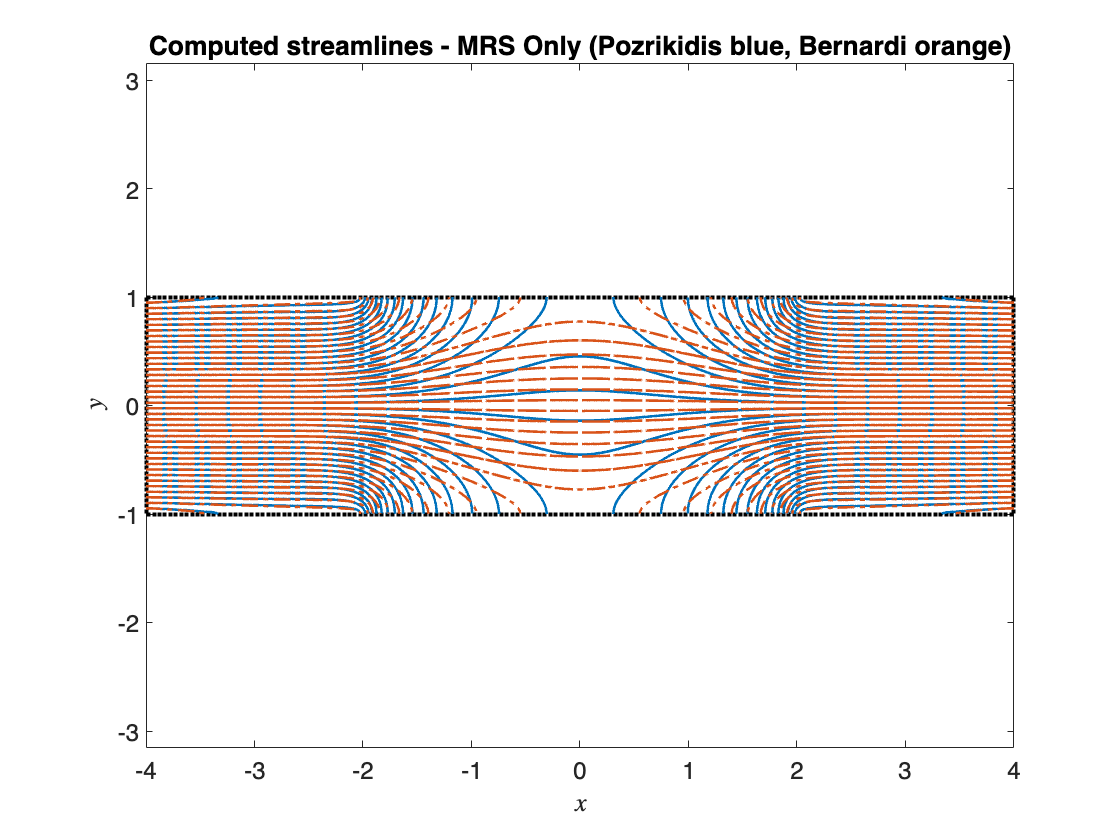

[x1gg, x2gg] = meshgrid(xx1, xx2);

figure
plot(y1, y2, 'k.')
hold on

% Computed streamlines
hh1_Pozrikidis = streamline(x1gg, x2gg, u1m_Pozrikidis', u2m_Pozrikidis', x1gg(1:end, 1), x2gg(1:end, 1)); % streamlines starting at left wall
hh2_Pozrikidis = streamline(x1gg, x2gg, -u1m_Pozrikidis', -u2m_Pozrikidis', x1gg(1:end, end), x2gg(1:end, end)); % streamlines starting at right wall

hh1_Bernardi = streamline(x1gg, x2gg, u1m_Bernardi', u2m_Bernardi', x1gg(1:end, 1), x2gg(1:end, 1)); % streamlines starting at left wall
hh2_Bernardi = streamline(x1gg, x2gg, -u1m_Bernardi', -u2m_Bernardi', x1gg(1:end, end), x2gg(1:end, end)); % streamlines starting at right wall

strmLW = 1.3;
RGB = orderedcolors("gem");
set(hh1_Pozrikidis, 'Color', RGB(1,:), 'linewidth', strmLW);
set(hh2_Pozrikidis, 'Color', RGB(1,:), 'linewidth', strmLW);
set(hh1_Bernardi, 'Color', RGB(2,:), 'LineStyle', '-.', 'linewidth', strmLW);
set(hh2_Bernardi, 'Color', RGB(2,:), 'LineStyle', '-.', 'linewidth', strmLW);

title('Computed streamlines - MRS Only (Pozrikidis blue, Bernardi orange)')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal
set(gca,'FontSize',12)

#### Quiver plot of exact velocities on boundaries for Pozrikidis

figure
subplot(2,1,1)

skip = 2;

plot(y1,y2,'k.')
hold on
quiver(x1m(1:skip:end,1:skip:end),x2m(1:skip:end,1:skip:end),u1m_Pozrikidis(1:skip:end,1:skip:end),u2m_Pozrikidis(1:skip:end,1:skip:end),1.5,'k','AutoScale','off')
quiver(y1(1:skip:end),y2(1:skip:end),u1_bd_Pozrikidis(1:skip:end),u2_bd_Pozrikidis(1:skip:end),1.5,'r','AutoScale','off')

title('Velocities from Pozrikidis BCs')
legend('','MRS Computed velocity','Boundary velocity')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal
set(gca,'FontSize',12)

#### pcolor plot of velocities everywhere with quiver of computed forces on boundaries for Pozrikidis

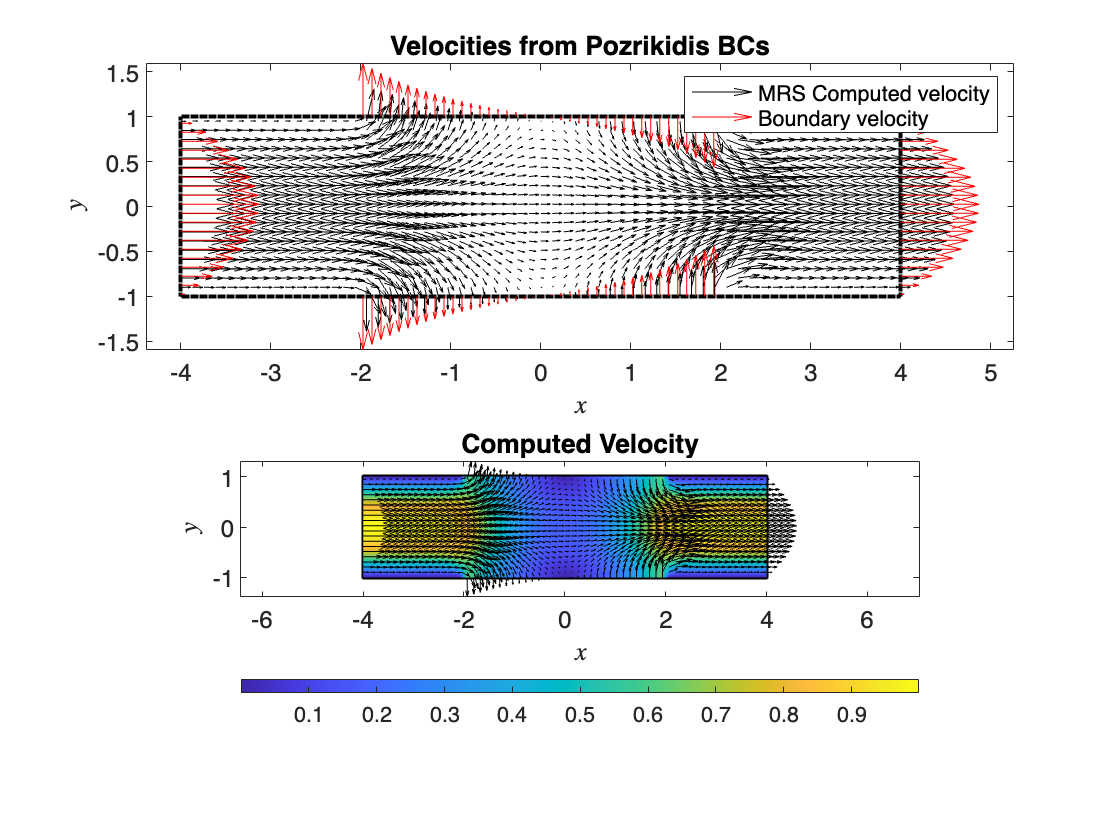

subplot(2,1,2)
skip = 2;
scalefactor = 1.5;

plot(y1,y2,'k.')
hold on
pcolor(x1m,x2m,ummag_Pozrikidis)
shading interp
colorbar('southoutside')
set(gca,'FontSize',12)

axis equal
quiver(x1m(1:skip:end,1:skip:end),x2m(1:skip:end,1:skip:end),u1m_Pozrikidis(1:skip:end,1:skip:end),u2m_Pozrikidis(1:skip:end,1:skip:end),scalefactor,'k','AutoScale','off')
title('Computed Velocity')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
set(gca,'FontSize',12)

#### Quiver plot of exact velocities on boundaries for Bernardi

figure
subplot(2,1,1)

skip = 2;

plot(y1,y2,'k.')
hold on
quiver(x1m(1:skip:end,1:skip:end),x2m(1:skip:end,1:skip:end),u1m_Bernardi(1:skip:end,1:skip:end),u2m_Bernardi(1:skip:end,1:skip:end),1.5,'k','AutoScale','off')
quiver(y1(1:skip:end),y2(1:skip:end),u1_bd_Bernardi(1:skip:end),u2_bd_Bernardi(1:skip:end),1.5,'r','AutoScale','off')

title('Velocities from Bernardi BCs')
legend('','MRS Computed velocity','Boundary velocity')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
axis equal
set(gca,'FontSize',12)

#### pcolor plot of velocities everywhere with quiver of computed forces on boundaries for Pozrikidis

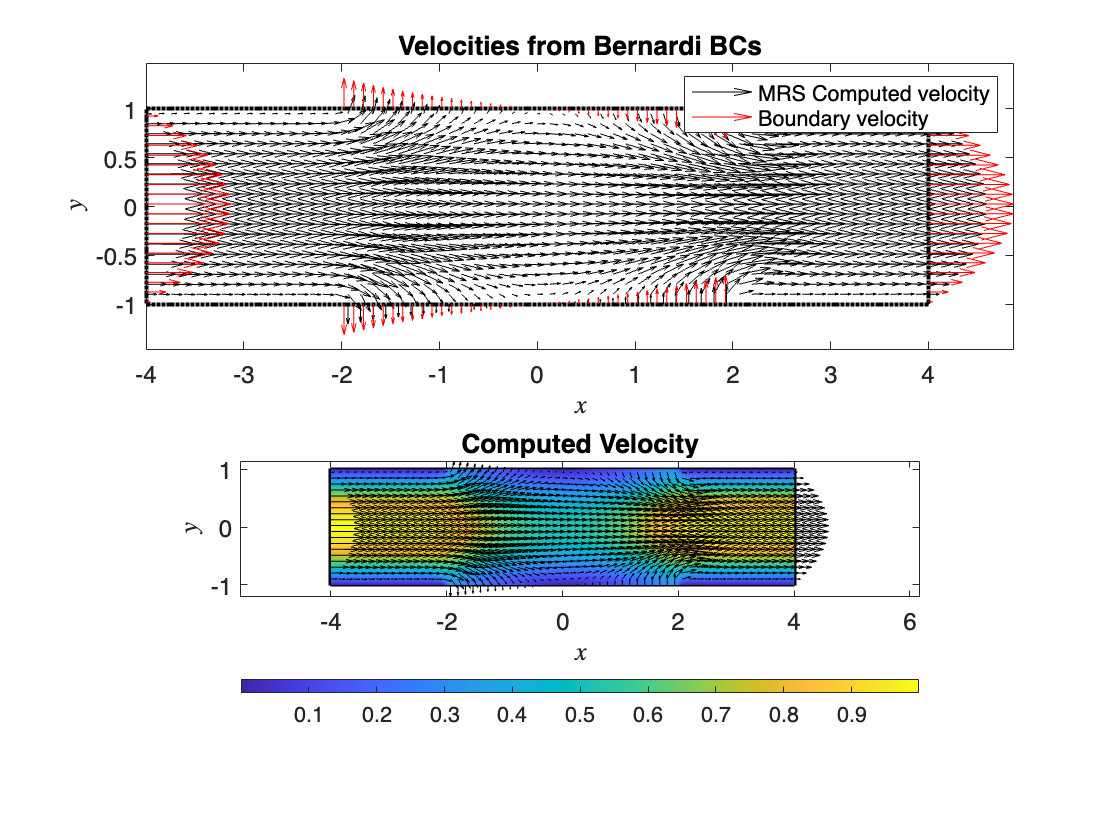

subplot(2,1,2)
skip = 2;
scalefactor = 1.5;

plot(y1,y2,'k.')
hold on
pcolor(x1m,x2m,ummag_Bernardi)
shading interp
colorbar('southoutside')
set(gca,'FontSize',12)

axis equal
quiver(x1m(1:skip:end,1:skip:end),x2m(1:skip:end,1:skip:end),u1m_Bernardi(1:skip:end,1:skip:end),u2m_Bernardi(1:skip:end,1:skip:end),scalefactor,'k','AutoScale','off')
title('Computed Velocity')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
set(gca,'FontSize',12)